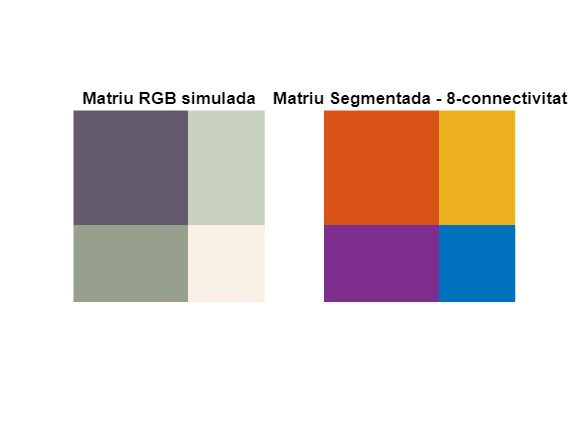

% PRACTICA 2: Segmentació de tres matrius (simulant RGB) amb creixement de regió

% Iniciem un comptador de temps per mesurar el temps total de segmentació
tic

% Definim tres matrius que simulen els canals R, G i B
matriu1 = [100 100 100 200 200;
           100 100 100 200 200;
           100 100 100 200 200;
           150 150 150 250 250;
           150 150 150 250 250];

matriu2 = [90 90 90 210 210;
           90 90 90 210 210;
           90 90 90 210 210;
           160 160 160 240 240;
           160 160 160 240 240];

matriu3 = [110 110 110 190 190;
           110 110 110 190 190;
           110 110 110 190 190;
           140 140 140 230 230;
           140 140 140 230 230];

% Convertim les matrius a tipus double per fer càlculs amb decimals
matriu1 = double(matriu1);
matriu2 = double(matriu2);
matriu3 = double(matriu3);

% Inicialitzem la matriu de resultat amb zeros (una etiqueta per píxel)
Resultat = zeros(size(matriu1));

% Inicialitzem paràmetres
etiqueta = 1;
th = 30;  % Llindar de distància euclidiana

% Tipus de connectivitat (4 o 8)
Conectivitat = 8;

% Utilitzem una cua estàtica (prealocada) per evitar redimensionaments constants i millorar rendiment
mida_cua = numel(matriu1);
vector_x = zeros(mida_cua, 1);
vector_y = zeros(mida_cua, 1);

% Busquem el primer píxel no etiquetat
[x, y] = find(Resultat == 0, 1);

% Bucle principal: mentre quedin píxels per etiquetar
while ~isempty(x)
    % Inicialitzem la mitjana per cada canal
    mitjana1 = matriu1(x, y);
    mitjana2 = matriu2(x, y);
    mitjana3 = matriu3(x, y);

    sumatori1 = mitjana1;
    sumatori2 = mitjana2;
    sumatori3 = mitjana3;

    comptador = 1;
    Resultat(x, y) = etiqueta;

    % Inicialitzem la cua
    inici = 1;
    final = 1;
    vector_x(final) = x;
    vector_y(final) = y;

    % Definim offsets segons connectivitat
    if Conectivitat == 4
        offsets = [ -1,  0;
                     0,  1;
                     1,  0;
                     0, -1];
    elseif Conectivitat == 8
        offsets = [ -1,  0;
                   -1,  1;
                    0,  1;
                    1,  1;
                    1,  0;
                    1, -1;
                    0, -1;
                   -1, -1];
    else
        error('El valor de Conectivitat ha de ser 4 o 8.');
    end

    % Inici del creixement de regió
    while (inici <= final)
        % 'inici' indica el pròxim píxel a processar
        % 'final' indica on afegim nous píxels a la cua
        x1 = vector_x(inici);
        y1 = vector_y(inici);
        inici = inici + 1;

        for i = 1:size(offsets, 1)
            pixel_x = x1 + offsets(i, 1);
            pixel_y = y1 + offsets(i, 2);

            if (pixel_x > 0 && pixel_x <= size(matriu1, 1) && pixel_y > 0 && pixel_y <= size(matriu1, 2))
                if (Resultat(pixel_x, pixel_y) == 0)
                    % Calculem la distància euclidiana RGB
                    distancia = sqrt( ...
                        (matriu1(pixel_x, pixel_y) - mitjana1)^2 + ...
                        (matriu2(pixel_x, pixel_y) - mitjana2)^2 + ...
                        (matriu3(pixel_x, pixel_y) - mitjana3)^2 );

                    if distancia < th
                        Resultat(pixel_x, pixel_y) = etiqueta;

                        final = final + 1;
                        vector_x(final) = pixel_x;
                        vector_y(final) = pixel_y;

                        sumatori1 = sumatori1 + matriu1(pixel_x, pixel_y);
                        sumatori2 = sumatori2 + matriu2(pixel_x, pixel_y);
                        sumatori3 = sumatori3 + matriu3(pixel_x, pixel_y);
                        comptador = comptador + 1;

                        mitjana1 = sumatori1 / comptador;
                        mitjana2 = sumatori2 / comptador;
                        mitjana3 = sumatori3 / comptador;
                    end
                end
            end
        end
    end

    % Busquem un nou píxel no etiquetat
    [x, y] = find(Resultat == 0, 1);
    etiqueta = etiqueta + 1;
end

% Convertim les etiquetes a una imatge RGB per visualitzar les regions
matriu_final = label2rgb(Resultat, lines(max(Resultat(:))), 'b', 'shuffle');

% Mostrem el resultat
figure;
subplot(1, 2, 1), imshow(cat(3, uint8(matriu1), uint8(matriu2), uint8(matriu3))), title('Matriu RGB simulada');
subplot(1, 2, 2), imshow(matriu_final), title(['Matriu Segmentada - ', num2str(Conectivitat), '-connectivitat']);


% Mostrem el temps total de segmentació
toc

Elapsed time is 0.784153 seconds.
